clear
close all
addpath("..\data\geojsonR01\")
addpath("..\data\matlabMobile\")

% センサーデータの読み込みとまとめ
load("himeji2shinosaka.mat")

sensor = synchronize(Acceleration,AngularVelocity,MagneticField,Orientation,Position,'union','previous');
sensor = rmmissing(sensor);
% 時間を初期値を0にする
sensor.Timestamp = sensor.Timestamp-sensor.Timestamp(1);

%センサーの時間切り出し
sensor = sensor(1:200000,:);

## 位置

% 移動平均のウィンドウサイズ
windowsize = 500;

% 時間を秒単位に変換
secondsTime = seconds(sensor.Timestamp);

% 加速度をまとめる
Acc = [sensor.X_Acceleration,sensor.Y_Acceleration,sensor.Z_Acceleration];

% バイアスの確認
AccBias = mean(Acc(1:500,:));
% % 下記と同義
% % X_AccBias = mean(sensor.X_Acceleration(1:500,1));
% % Y_AccBias = mean(sensor.Y_Acceleration(1:500,1));
% % Z_AccBias = mean(sensor.Z_Acceleration(1:500,1));

% バイアスの修正
Acc = Acc-AccBias;
% % 下記と同義
% % X_Acc = sensor.X_Acceleration-X_AccBias;
% % Y_Acc = sensor.Y_Acceleration-Y_AccBias;
% % Z_Acc = sensor.Z_Acceleration-Z_AccBias;

% 移動平均をとる

movmeanAcc = movmean(Acc,windowsize);

% 速度
Vel = cumtrapz(secondsTime,Acc,1);
movmeanVel = cumtrapz(secondsTime,movmeanAcc,1);

% 位置
Pos = cumtrapz(secondsTime,Vel,1);
movmeanPos = cumtrapz(secondsTime,movmeanVel,1);

## プロットで確認

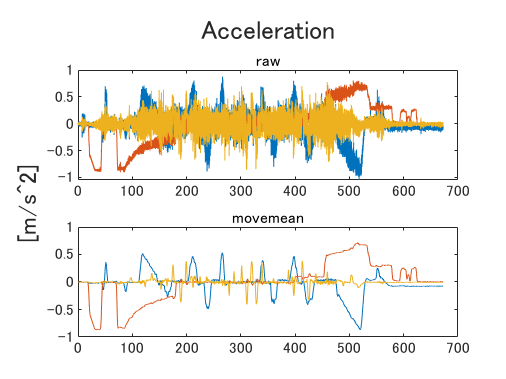

% 加速度
figure;
t = tiledlayout(2,1,'TileSpacing','Compact');
nexttile;
plot(secondsTime,Acc)
title("raw")
nexttile;
plot(secondsTime,movmeanAcc)
title("movemean")
title(t,'Acceleration')
ylabel(t,'[m/s^2]','Interpreter','none')

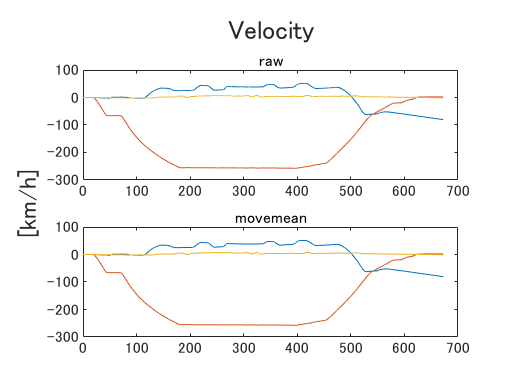

% 速度
figure;
t = tiledlayout(2,1,'TileSpacing','Compact');
nexttile;
plot(secondsTime,Vel*3600/1000)
title("raw")
nexttile;
plot(secondsTime,movmeanVel*3600/1000)
title("movemean")
title(t,'Velocity')
ylabel(t,'[km/h]','Interpreter','none')

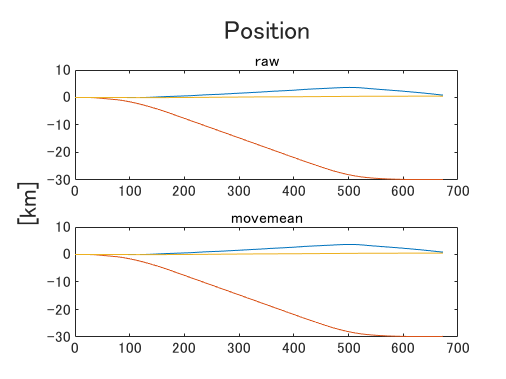

% 位置
figure;
t = tiledlayout(2,1,'TileSpacing','Compact');
nexttile;
plot(secondsTime,Pos/1000)
title("raw")
nexttile;
plot(secondsTime,movmeanPos/1000)
title("movemean")
title(t,'Position')
ylabel(t,'[km]','Interpreter','none')

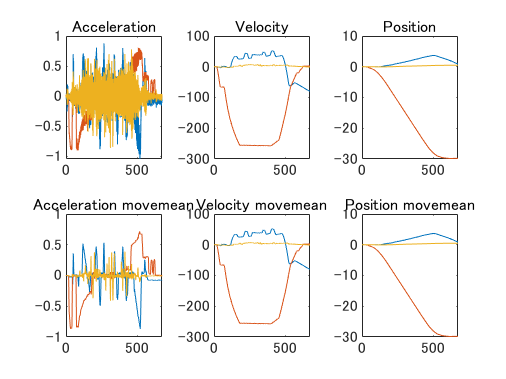

% まとめのプロット
figure
tiledlayout(2,3)
% 加速度
nexttile;
plot(secondsTime,Acc)
title("Acceleration")
% 速度
nexttile;
plot(secondsTime,Vel*3600/1000)
title("Velocity")
% 位置
nexttile;
plot(secondsTime,Pos/1000)
title("Position")
% 移動平均
% 加速度
nexttile;
plot(secondsTime,movmeanAcc)
title("Acceleration movemean")
% 速度
nexttile;
plot(secondsTime,Vel*3600/1000)
title("Velocity movemean")
% 位置
nexttile;
plot(secondsTime,movmeanPos/1000)
title("Position movemean")

## 角度についてのデータ

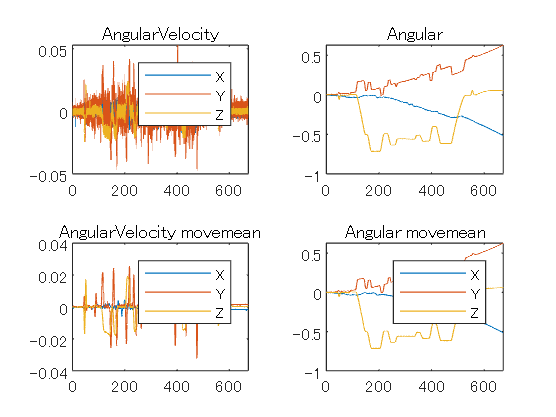

windowsize = 500;
secondsTime = seconds(sensor.Timestamp);
% 角度まとめる
AngVel = [sensor.X_AngularVelocity,sensor.Y_AngularVelocity,sensor.Z_AngularVelocity];
% バイアスの確認
AngVelBias = mean(AngVel(1:500,:));
% X_AngVelBias = mean(sensor.X_AngularVelocity(1:500,1));
% Y_AngVelBias = mean(sensor.Y_AngularVelocity(1:500,1));
% Z_AngVelBias = mean(sensor.Z_AngularVelocity(1:500,1));

% 角速度のバイアス修正
AngVel = AngVel-AngVelBias;
% X_AngVel = sensor.X_AngularVelocity-X_AngVelBias;
% Y_AngVel = sensor.Y_AngularVelocity-Y_AngVelBias;
% Z_AngVel = sensor.Z_AngularVelocity-Z_AngVelBias;
%トレンドの修正
% X_AngVel = detrend(X_AngVel,1);
% Y_AngVel = detrend(Y_AngVel,1);
% Z_AngVel = detrend(Z_AngVel,1);

figure
tiledlayout(2,2);
nexttile;
plot(secondsTime,AngVel)
legend(["X","Y","Z"])
title("AngularVelocity")
%角度変化
nexttile
Ang = cumtrapz(secondsTime,AngVel,1);
% 下の方法と同義
% X_Ang = cumtrapz(secondsTime,X_AngVel)
% Y_Ang = cumtrapz(secondsTime,Y_AngVel)
% Z_Ang = cumtrapz(secondsTime,Z_AngVel)
plot(secondsTime,Ang)
title("Angular")

%移動平均のプロット
nexttile;
movmeanAngVel = movmean(AngVel,windowsize);
plot(secondsTime,movmeanAngVel)
legend(["X","Y","Z"])
title("AngularVelocity movemean")
nexttile;
movmeanAng = cumtrapz(secondsTime,movmeanAngVel,1);
plot(secondsTime,movmeanAng)
legend(["X","Y","Z"])
title("Angular movemean")

## 緯度と経度に沿うよう変換

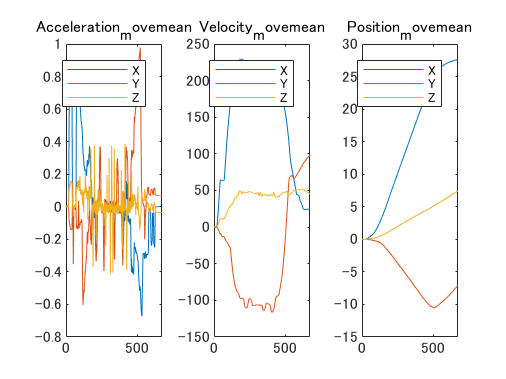

%　逆行列
rotmZYX = eul2rotm([-movmeanAng(:,3)+pi/2+0.15,-movmeanAng(:,2)+0.2,-movmeanAng(:,1)-0.2]);

movmeanAcc2 = pagemtimes(rotmZYX,permute(movmeanAcc,[2,3,1]));
movmeanAcc2 = permute(movmeanAcc2,[3,1,2]);
% Y方向の反転
movmeanAcc2(:,2) = -movmeanAcc2(:,2);

figure
tiledlayout(1,3);
% 加速度
nexttile;
plot(secondsTime,movmeanAcc2)
legend(["X","Y","Z"])
title("Acceleration_movemean")
% 速度
nexttile;
movmeanVel = cumtrapz(secondsTime,movmeanAcc2,1);
plot(secondsTime,movmeanVel*3600/1000)
legend(["X","Y","Z"])
title("Velocity_movemean")
% 位置
nexttile;
movmeanPos = cumtrapz(secondsTime,movmeanVel,1);
plot(secondsTime,movmeanPos/1000)
legend(["X","Y","Z"])
title("Position_movemean")

% 距離から緯度経度の計算
% 一ステップ間で経度計算時は緯度は一定とする，
% 地球は球面とする．地球半径R＝6378137m
% 緯度の差分：rad2deg(Y方向移動[m]/R)
% 経度の差分：rad2deg(x方向移動/r) ,ただしr = R*cos(緯度)
initLatitude = sensor.latitude(1);
initLongtitude = sensor.longitude(1);
R = 6378137;
% 緯度方向の計算 
odomLatitude = rad2deg(movmeanPos(:,2)/R) + initLatitude;
odomLongtitude = rad2deg(movmeanPos(:,1)./(R*cosd(odomLatitude))) + initLongtitude;

## geoplot

figure
gx = geoaxes;
hold(gx);

現在のプロットをホールドしました


%% GISデータのプロット
txt = readlines("N02-19_RailroadSection.geojson");
txt = strrep(txt,'鉄道区分','railsegments');
txt = strrep(txt,'事業者種別','companysegments');
txt = strrep(txt,'路線名','railname');
txt = strrep(txt,'運営会社','company');
geojson = jsondecode(strjoin(txt))

geojson = フィールドをもつ struct :
        type: 'FeatureCollection'
    features: [22016×1 struct]


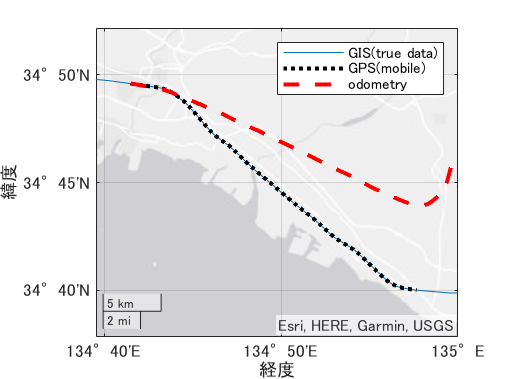

%　山陽新幹線
railname = ["山陽新幹線"];
company = ["西日本旅客鉄道"];
color = ["#0072BA"];

for ii=1:length(railname)
    plotCoordinate(gx,geojson,railname(ii),company(ii),color(ii))
end

% ログデータのプロット
geoplot(gx,sensor.latitude,sensor.longitude,'k:',LineWidth=2)
geoplot(gx,odomLatitude,odomLongtitude,'r--',LineWidth=2)
hold off
legend(["GIS(true data)","GPS(mobile)", "odometry"])

geolimits([34.64 34.86],[134.659 135.00])

function plotCoordinate(gx,geojson,railName,company,color)
    railcoordinate = [];
        for ii=1:length(geojson.features)
        if string(geojson.features(ii).properties.railname)==railName && string(geojson.features(ii).properties.company)==company
            railcoordinate = [railcoordinate;geojson.features(ii).geometry.coordinates];
        end
        end
        railcoordinate = sortrows(railcoordinate);
        geoplot(gx,railcoordinate(:,2),railcoordinate(:,1),"Color",color);
end